Define equations for point sources and sinks

syms x y a b u 

sinks = log(sqrt((x-a).^2 + (y-b).^2));
sources = -log(sqrt((x-a).^2 + (y-b).^2));

Walls

a_vals = [u u -1.5 2.5];
b_vals = [-3.37 1 u u];
u_low = [-1.5 -1.5 -3.37 -3.37];
u_high = [2.5 2.5 1 1];

walls = 0;
for i = 1:length(a_vals)
    for u_actual = u_low(:,i):0.2:u_high(:,i)
        a_actual = subs(a_vals(:,i), u, u_actual);
        b_actual = subs(b_vals(:,i), u, u_actual);
        walls = walls + subs(sinks, [a b], [a_actual b_actual]);
    end
end

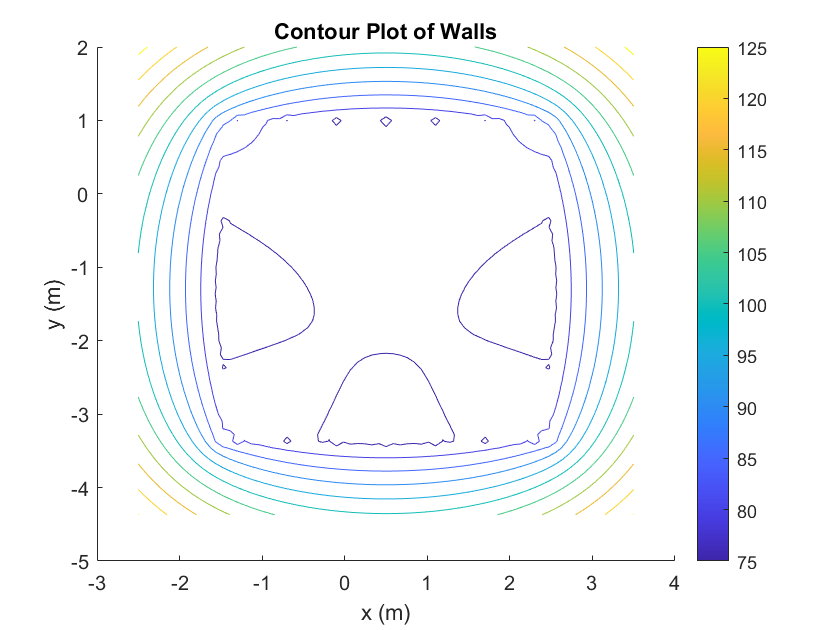

xyinterval = [-1.5-1 2.5+1 -3.37-1 1+1];
figure(); clf; hold on;
fcontour(walls, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
title("Contour Plot of Walls");
colorbar

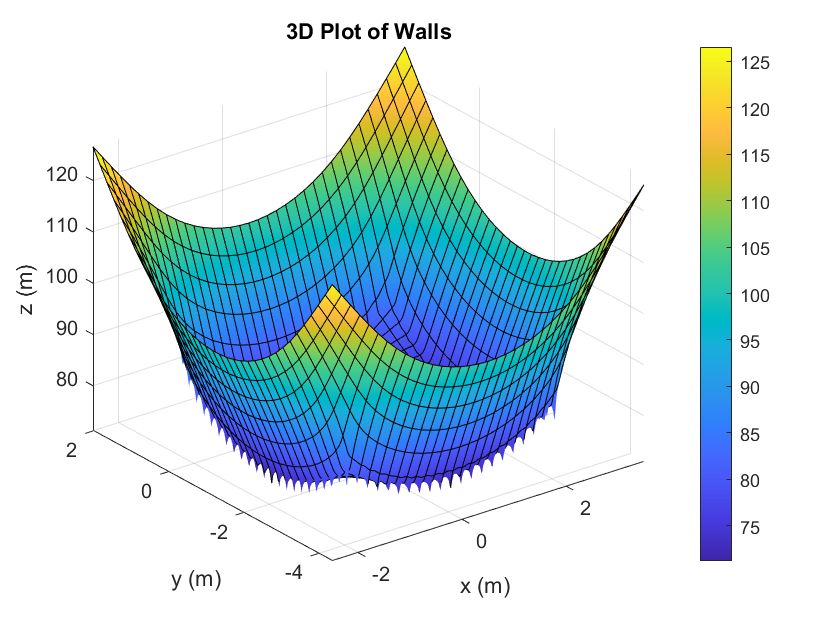

figure(); clf;
fsurf(walls, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
title("3D Plot of Walls")
colorbar

BoB

BoB_eq = log10(sqrt((x-a).^2 + (y-b).^2));

BoB = 0; r = 0.25;
for theta = 0:0.1:2*pi
    a_actual = r*cos(theta) + 0.75;
    b_actual = r*sin(theta) - 2.5;
    BoB = BoB + subs(BoB_eq, [a b], [a_actual b_actual]);
end

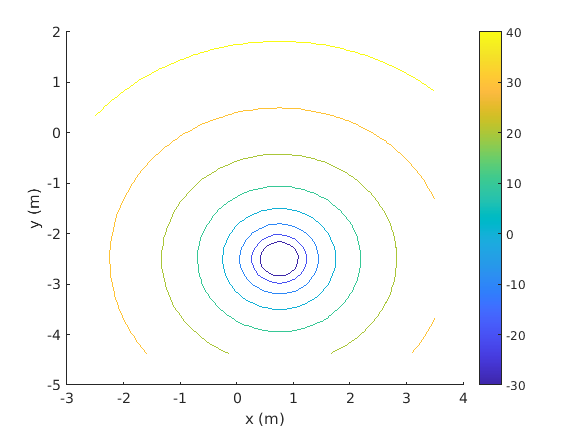

figure(); clf; hold on;
fcontour(BoB, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

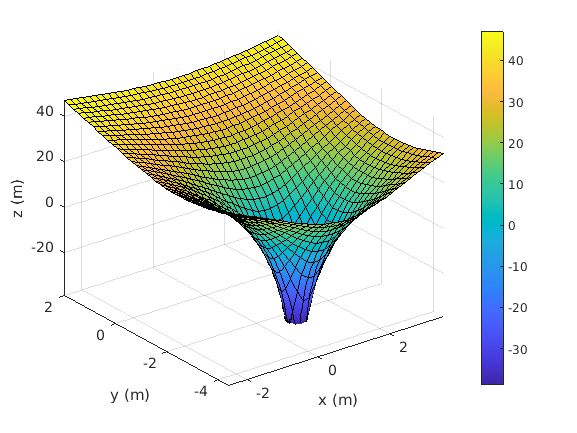

figure(); clf;
fsurf(BoB, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

Obstacles

% Obstacle at (1.41, -2)
center = [1.41; -2]; 
sidelength = 0.5;
offset = sidelength/2;

a_vals = [u u 1.41-offset 1.41+offset];
b_vals = [-2-offset -2+offset u u];
u_low = [1.41-offset 1.41-offset -2-offset -2-offset];
u_high = [1.41+offset 1.41+offset -2+offset -2+offset];
theta_actual = 0;       % degrees

syms theta
rot_matrix = [cosd(theta) -sind(theta);
              sind(theta) cosd(theta)];

obstacles = 0;
for i = 1:length(a_vals)
    for u_actual = u_low(:,i):0.2:u_high(:,i)
        a_actual = subs(a_vals(:,i), u, u_actual);
        b_actual = subs(b_vals(:,i), u, u_actual);
        
        rot_matrix_actual = subs(rot_matrix, theta, theta_actual);
        rotated_point = rot_matrix_actual * [x - center(1,:); y - center(2,:)] ...
            + center;
        obstacles = obstacles + subs(sources, [a b x y], ...
            [a_actual b_actual rotated_point(1,:) rotated_point(2,:)]);
    end
end

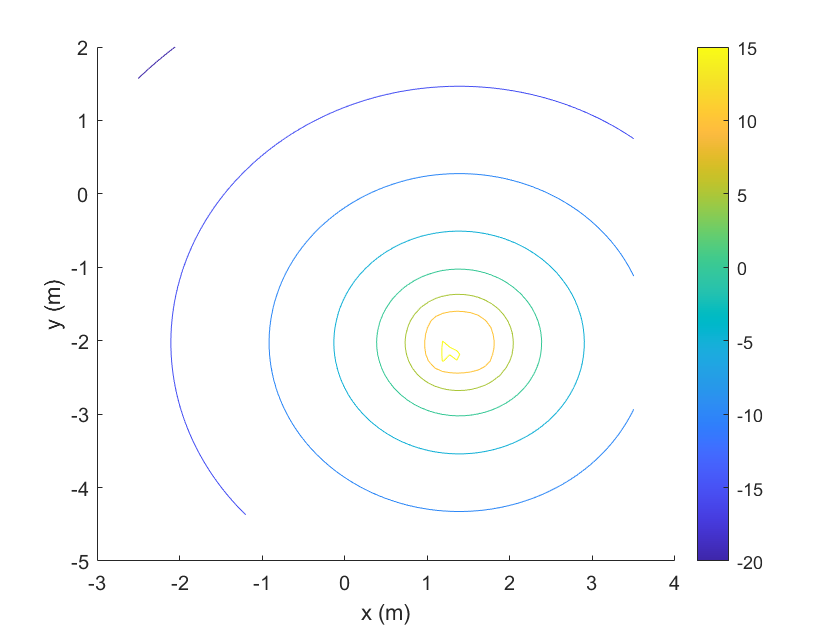

xyinterval = [-1.5-1 2.5+1 -3.37-1 1+1];
figure(); hold on;
fcontour(obstacles, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

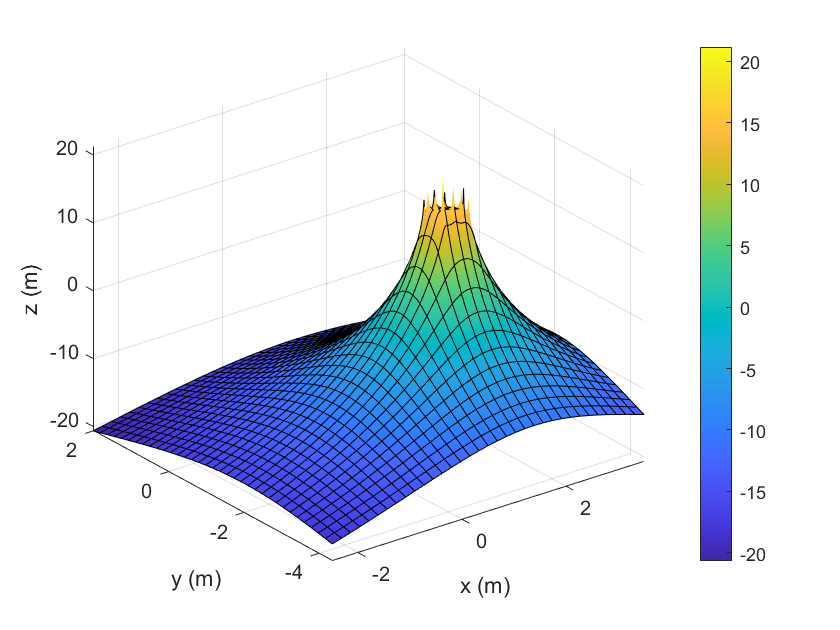

figure(); clf;
fsurf(obstacles, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

% Obstacle at (1, -0.7) rotated 45deg
center = [1; -0.7]; 
sidelength = 0.5;
offset = sidelength/2;

a_vals = [u u 1-offset 1+offset];
b_vals = [-0.7-offset -0.7+offset u u];
u_low = [1-offset 1-offset -0.7-offset -0.7-offset];
u_high = [1+offset 1+offset -0.7+offset -0.7+offset];
theta_actual = 45;       % degrees

syms theta
rot_matrix = [cosd(theta) -sind(theta);
              sind(theta) cosd(theta)];

for i = 1:length(a_vals)
    for u_actual = u_low(:,i):0.2:u_high(:,i)
        a_actual = subs(a_vals(:,i), u, u_actual);
        b_actual = subs(b_vals(:,i), u, u_actual);
        
        rot_matrix_actual = subs(rot_matrix, theta, theta_actual);
        rotated_point = rot_matrix_actual * [x - center(1,:); y - center(2,:)] ...
            + center;
        obstacles = obstacles + subs(sources, [a b x y], ...
            [a_actual b_actual rotated_point(1,:) rotated_point(2,:)]);
    end
end

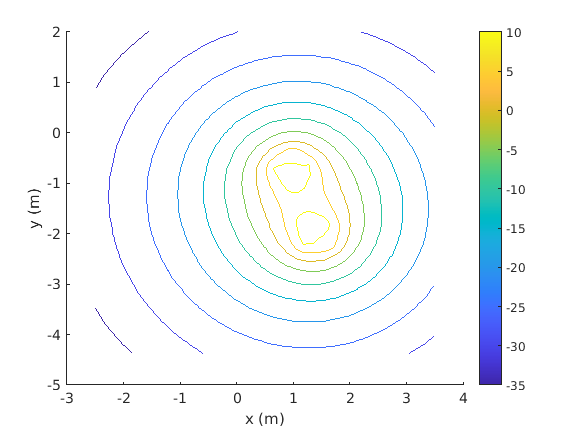

xyinterval = [-1.5-1 2.5+1 -3.37-1 1+1];
figure(); hold on;
fcontour(obstacles, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

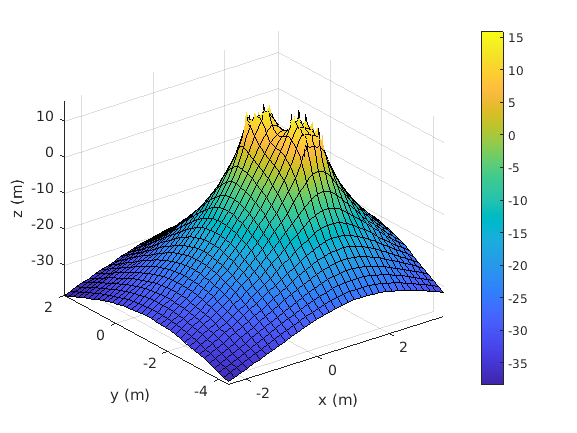

figure(); clf;
fsurf(obstacles, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

% Obstacle at (-0.25, -1) rotated 45deg
center = [-0.25; -1]; 
sidelength = 0.5;
offset = sidelength/2;

a_vals = [u u -0.25-offset -0.25+offset];
b_vals = [-1-offset -1+offset u u];
u_low = [-0.25-offset -0.25-offset -1-offset -1-offset];
u_high = [-0.25+offset -0.25+offset -1+offset -1+offset];
theta_actual = 45;       % degrees

syms theta
rot_matrix = [cosd(theta) -sind(theta);
              sind(theta) cosd(theta)];

for i = 1:length(a_vals)
    for u_actual = u_low(:,i):0.2:u_high(:,i)
        a_actual = subs(a_vals(:,i), u, u_actual);
        b_actual = subs(b_vals(:,i), u, u_actual);
        
        rot_matrix_actual = subs(rot_matrix, theta, theta_actual);
        rotated_point = rot_matrix_actual * [x - center(1,:); y - center(2,:)] ...
            + center;
        obstacles = obstacles + subs(sources, [a b x y], ...
            [a_actual b_actual rotated_point(1,:) rotated_point(2,:)]);
    end
end

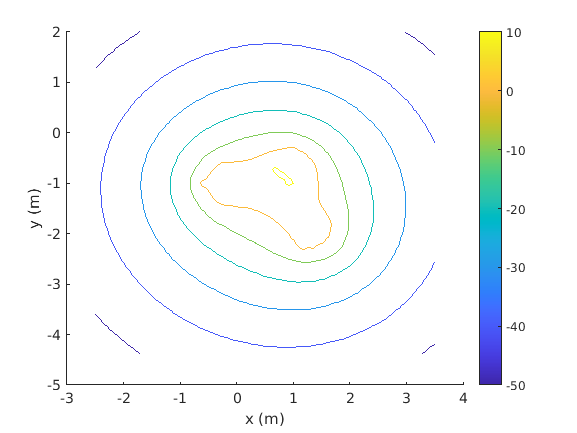

xyinterval = [-1.5-1 2.5+1 -3.37-1 1+1];
figure(); hold on;
fcontour(obstacles, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

figure(); clf;
fsurf(obstacles, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

All together now!

mega_equation = (2*BoB + walls + 0.7*obstacles);

Run this section to get LIDAR scan

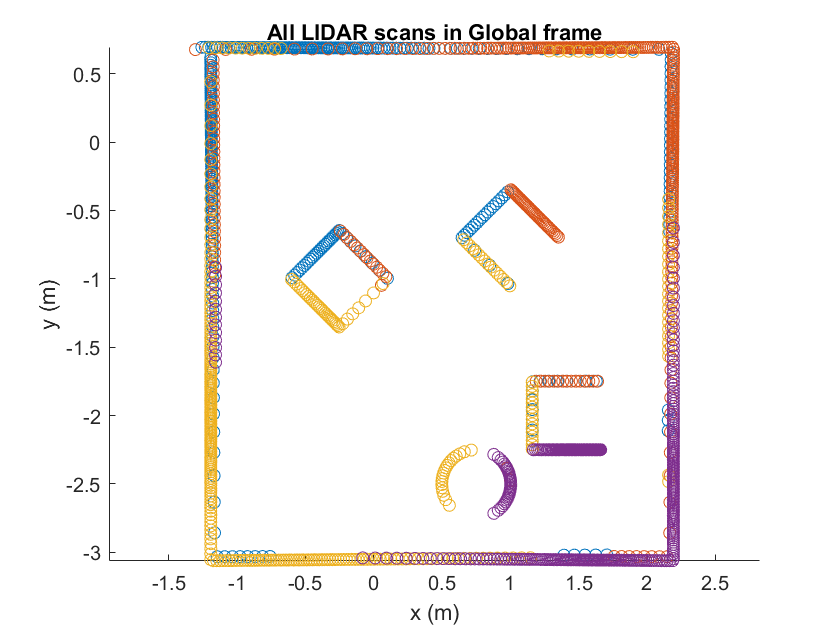

load('mydata.mat','r_all','theta_all');

% The origin of the Neato frame in the Global frame.
% Each row corresponds to the origin for a particular scan
origins = [-0.5 0; 1.5 0; -0.5 -2; 1.5 -2.5];

% the orientation of the Neato relative to the Global frame in radians.
% A positive angle here means the Neato's ihat_N axis was rotated
% counterclockwise from the ihat_G axis.
orientations = [-pi/3 -2*pi/3 0 pi];

% the origin of the Lidar frame in the Neato frame (ihat_N, jhat_N).
origin_of_lidar_frame = [-0.084 0];

allScansFig = figure;

cartPtsInGFrame = [];

% for each scan
for i = 1 : size(origins,1)
    cartesianPointsInLFrame = [cos(theta_all(:,i)).*r_all(:,i)...
                               sin(theta_all(:,i)).*r_all(:,i)]';
    
    % add a row of all ones so we can use translation matrices
    cartesianPointsInLFrame(end+1,:) = 1;
    cartesianPointsInNFrame = [1 0 origin_of_lidar_frame(1);...
                               0 1 origin_of_lidar_frame(2);...
                               0 0 1]*cartesianPointsInLFrame;

    rotatedPoints = [cos(orientations(i)) -sin(orientations(i)) 0;...
                     sin(orientations(i)) cos(orientations(i)) 0;...
                     0 0 1]*cartesianPointsInNFrame;
                 
    cartesianPointsInGFrame = [1 0 origins(i,1);...
                               0 1 origins(i,2);...
                               0 0 1]*rotatedPoints;
    
    figure(allScansFig);
    scatter(cartesianPointsInGFrame(1,:), cartesianPointsInGFrame(2,:), 'HandleVisibility', 'off');
    hold on;
    title('All scans in Global frame');                              
end
save('cartesianPointsInGFrame', 'cartPtsInGFrame')
% display the figure that contains all of the scans

figure(allScansFig);
hold on;
title('All LIDAR scans in Global frame'); 
xlabel("x (m)"); ylabel("y (m)"); axis equal;

Superimpose contour plot on LIDAR scans for context

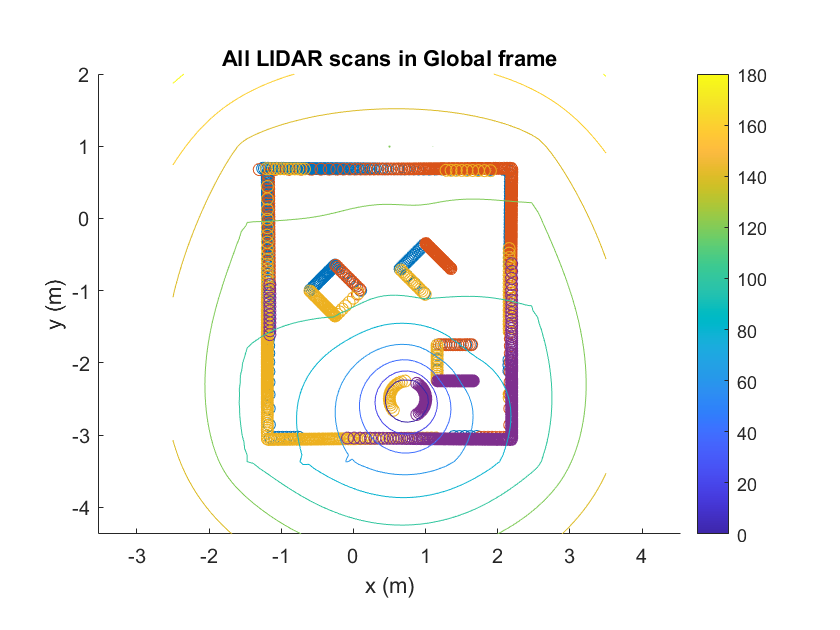

figure(allScansFig); hold on;
fcontour(mega_equation, xyinterval, 'HandleVisibility', 'off');
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

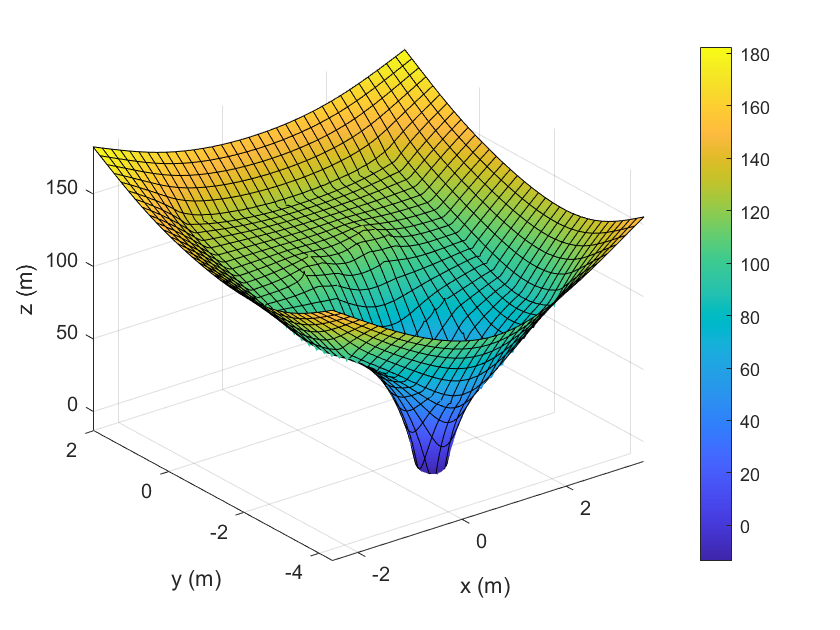

figure(); clf;
fsurf(mega_equation, xyinterval);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
colorbar

g = gradient(mega_equation, [x y]);

[X, Y] = meshgrid(-5:.71:5,-5:.71:5);
G1 = subs(g(1),[x y],{X,Y});
G2 = subs(g(2),[x y],{X,Y});

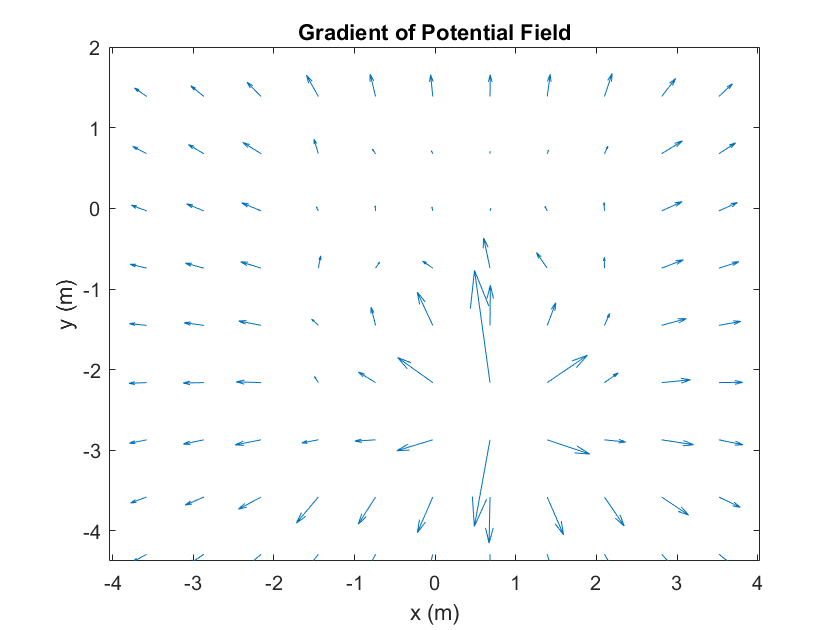

figure(); clf;
quiver(X,Y,G1,G2,1.5);
xlim([-1.5-1 2.5+1]); ylim([-3.37-1 1+1]);
xlabel("x (m)"); ylabel("y (m)"); axis equal;
title("Gradient of Potential Field")

Week 5 starter code from HW

% You can tweak these for fun
delta_0 = 0.19; % 1.1;
lambda_0 = 0.835;
step_length = 0.1;
r_0 = [0, 0];        % [x, y] initial position

syms x y
% Make BoB positive for gradient ascent algorithm
f = mega_equation;

Unrecognized function or variable 'mega_equation'.


f_gradient = -1*gradient(f);

% Initialize data storage
r = r_0;        % [x, y] final points
steps = [];  % change in position between steps [dx, dy]
lambda = lambda_0;
delta = delta_0;
num_gradient = 100;

while norm(num_gradient) >= 0.5 & size(r,1) < 100
    % Calculate gradient at point
    x_pos = r(end, 1);   % get current position to solve
    y_pos = r(end, 2);
    
    num_gradient = subs(f_gradient, [x y], [x_pos y_pos]);
    
    % Record data
    lambda = delta * lambda;
    pos_change = num_gradient * lambda;
    x_change = pos_change(1,1);
    y_change = pos_change(2,1);
    steps(end+1,1) = x_change;
    steps(end+1,2) = y_change;
    r(end+1,1) = r(end,1) + x_change;
    r(end,2) = r(end-1,2) + y_change;
end

figure(allScansFig); hold on;

fcontour(mega_equation, xyinterval, "HandleVisibility", 'off');

Unrecognized function or variable 'mega_equation'.

xlabel("x (m)"); ylabel("y (m)"); axis equal;
colorbar

plot(r(:,1), r(:,2), 'b-o'); %, 'DisplayName', 'Planned');

Unrecognized function or variable 'r'.

xlim([-1.5-1 2.5+1]); ylim([-3.37-1 1+1]);

Data Analysis

encoder_data = readmatrix('encoder_data.csv');

timeseconds = encoder_data(:,1);
encoderLeftmeters = encoder_data(:,2);
encoderRightmeters = encoder_data(:,3);

driveTime = timeseconds(end) - timeseconds(1)   % seconds

driveTime = 36.8000

Plot

% Set parameter for distance between wheels
d = 0.235;      % m

% Find wheel velocities
velocityLeft = diff(encoderLeftmeters) ./ diff(timeseconds);
velocityRight = diff(encoderRightmeters) ./ diff(timeseconds);

% Find angular velocity
omega_actual = (velocityRight - velocityLeft) ./ d;  % rad/s

% Find linear speed
speed_actual = (velocityLeft + velocityRight) ./ 2; % m/s

% Integrate the angular velocity to get theta
theta_integrated = cumtrapz(timeseconds(1:end-1,:), omega_actual);

% Get speed components from actual speed
speed_x = speed_actual .* cos(theta_integrated);
speed_y = speed_actual .* sin(theta_integrated);

% Integrate speed components to get location coordinates
pos_x = cumtrapz(timeseconds(1:end-1,:), speed_x);
pos_y = cumtrapz(timeseconds(1:end-1,:), speed_y);
location_actual = [pos_x pos_y]';

location_final =     0.6596
   -2.3776


distance = 2.4674

% Calculate total distance traveled
(encoderLeftmeters(end)-encoderLeftmeters(1) + encoderRightmeters(end)-encoderRightmeters(1)) / 2

ans = 2.4691

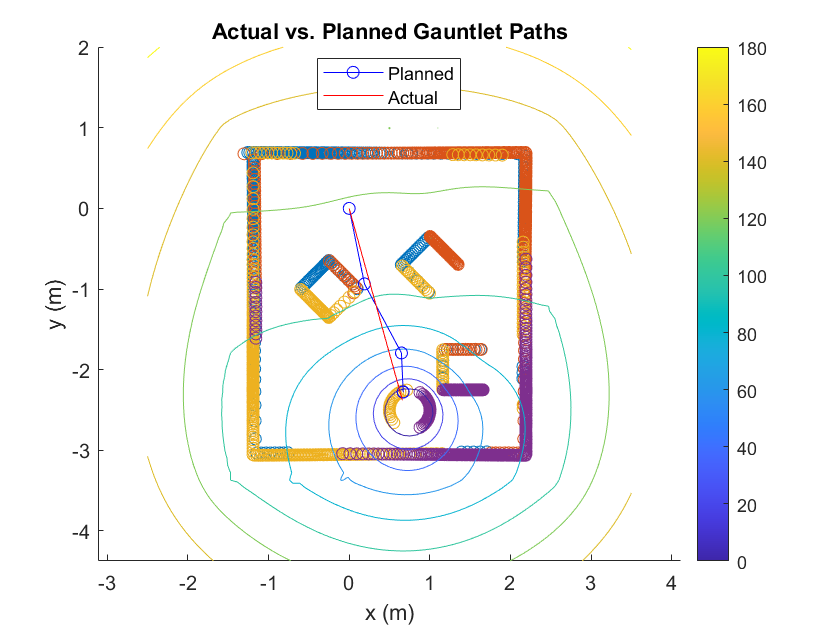

% Plotting the position curve
figure(allScansFig); hold on; legend("Location", "best"); axis equal;
title("Actual vs. Planned Gauntlet Paths"); xlabel("x (m)"); ylabel("y (m)");
plot(location_actual(1,:), location_actual(2,:), "r-"); %, 'DisplayName', "Actual");
legend({"Planned", "Actual"});